# Global sensitivity and uncertainty analysis toolbox (GSUA)

## 1. Introduction

The [GSUA Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/47758-global-sensitivity-and-uncertainty-analysis-gsua-of-dynamical-systems-using-variance-based-methods) implements uncertainty and global and local (OAT) sensitivity analysis of dynamical and static models. The toolbox only needs the following information (**see examples**):

- A mathematical model in a Simulink or m-file. In the case of a Simulink Model, it is neccesarry some simple special structure: use a "**To Workspace**" connected to the output with **sample time,**  Variable name "yout" and "Structure with time" format. The parameters of models are defined with variable x. In the case of a m-file (ss model or ode model), see examples for information about the configuration of file.

- A m-file with these data: 1) a description of the model, 2) a cell with Np factor names (they are necessary to a good analysis), 3) a (2xNp) matrix with nominal values in the first row and uncertainty percent in the second row, 4) name of file with the model (Simulink model or m-file model).

In the dynamical case the toolbox compute uncertainty and sensitivity plots for two functions:

- **Vectorial output** $y\left(t\right)$ or time response. Plots: 1) uncertainty plot as a time response (the nominal or experimental time output is highlighted), 2) plot of vectorial first-order sensitivity indices which depend on time, 3) plot of vectorial total sensitivity indices which depend on time.

- **Scalar characteristic** $y_s$ obtained from time response. Examples: squared error (adjust to a nominal or experimental time response), peak time, rise time, settling time, settling or final value, overshoot, etc. (it is possible to include manually other scalar characteristics). So, with the sensitivity analysis is possible to analyze the effect of every factor in some time output characteristic. Plots: 4) scalar first-order sensitivity indices for the scalar output $y_s$ using pie or bar plots, 5) scalar total sensitivity indices for the scalar output $y_s$ using pie or bar plots, 6) scatter plots (show the posible dependence between output $y_s$ and each factor).

For static models (simple mathematical functions) the toolbox compute uncertainty and sensitivity plots for two functions

- **Scalar output **$y=f\left(x_1 ,x_2 ,\cdots \right)$. Plots: 1) uncertainty plot as a histogram plot which shows how the output varies with changes on factors, 2) scalar first-order sensitivity indices for the scalar output $y$ using pie or bar plots, 3) scalar total sensitivity indices for the scalar output $y$ using pie or bar plots.

- **Scalar characteristic** $y_s$ obtained from $y$. Example: squared error (adjust to a nominal or experimental value). Plots: 4) scalar first-order sensitivity indices for the scalar output $y_s$ using pie or bar plots, 5) scalar total sensitivity indices for the scalar output $y_s \;$using pie or bar plots, 6) scatter plots (show the posible dependence between output $y_s$ and each factor).

## 2. Model information

In this section, the basic model information is defined. 

**model data: **m-file with this information (see examples):

- **description** (optional): description of the model.

- **factor_names**: factor names in cell format. Factors: parameters and initial conditions.

- **x**: two-rows matrix with parameter information: nominal values of factors in the first row and uncertainty (in percent) of every factor in the second row. In the case when uncertainty is given in intervals or standard deviation, it is necessary to transform it to percent (a easy task). **If the nominal value is a zero**, it is necessary to represent the parameter (a = 0 ± da) like (a = a1 - da) with a1 = da ± da and da without any error.

- **model: **name of file with the model. The model file may be a Simulink model or a m-file model (see examples); the m-file model may be a lineal state-space model or a model solved using ode45 function. The Simulink model uses a lot of more computational time, but is the prefered method for hybrid dynamical systems (systems with continuous and discrete subsystems).

clc
S = [];
model_selection = "ControlLineal_data"; model_example = 'mass_spring_data';
if strcmp(model_selection,'Example')
    S.model_data = model_example;
    Txt = 'Example model description: ';
else
    S.model_data = model_selection;
    Txt = 'External model description: ';
end
 
if exist(S.model_data,'file') == 0
    disp('The model file does not exist (review the file name or path to the file)')
    return
end
run(S.model_data)
if exist(S.model,'file')==4
    S.model_type = 'Simulink model';
else
    S.model_type = 'M-file model';
end
disp([Txt S.description])

External model description: Control del Crecimiento de un Tumor


disp(['Type of model: ' S.model_type])

Type of model: Simulink model


S.T = table(S.x(1,:)',S.x(2,:)','RowNames',S.factor_names','VariableNames',{'Nominal values','Uncertainty(%)'});
clear model_selection model_example description Txt
disp('Model parameters and uncertainties:')

Model parameters and uncertainties:


disp(S.T)

             Nominal values    Uncertainty(%)
             ______________    ______________

    a1              0.2              20      
    a2              0.3              20      
    a3              0.1              20      
    b1                1              20      
    b2                1               0      
    alpha           0.3              20      
    c1                1              20      
    c2              0.5              20      
    c3                1              20      
    c4                1              20      
    d1              0.2              20      
    d2                1              20      
    r1              1.5              19      
    r2   

## 3. Configuration of sensitivity method

In this section, the main information of the sensitivity method is defined, the compute is done, and the results are saved in a file for their future use.

S.sens_method = 'OAT'; S.sample_method = 'LatinHypercube'; S.N = 20; % Number of samples
S.scalar_characteristic = 'sum((y-ynom).^2)'; S.ynom = "Nominal";  
S.rngN = 0;
 
S.Np = size(S.x,2);
if exist(S.ynom,'var')==0 || strcmp(S.ynom,'Nominal')==1
    S.ynom = 'Nominal';
    disp('Using data generated with nominal parameter values')
else
    S.ynom = eval(S.ynom);
    if iscolumn(S.ynom)
        S.ynom = S.ynom';
    end
    disp('Using experimental data')
end

Using data generated with nominal parameter values


S = gsua_sample(S); % Monte Carlo sampling
S = gsua_methods(S); % Uncertainty ans sensitivity analysis

Estimated computing time: 0h:0m:54s
Estimated stop time: 7:54:3


% The results are saved in a file
D = which('gsua_main.mlx');
D = D(1:end-13);
if ~exist([D 'Results'],'dir')
    mkdir([D 'Results'])
end
save([D 'Results\' S.model '_' S.sens_method '_' S.sample_method(1:3) '_' num2str(S.N) '_' ...
    S.scalar_characteristic '_' num2str(S.x(2,1)) '.mat'],'S')
clear D

## 4. Method information

S.labels_uncer = cell(1,S.Np);
for i=1:S.Np
    S.labels_uncer(i) = {[S.factor_names{i} '(' num2str(S.x(2,i),2) '%)  ']};
end
clear i
S.sim_resume = {...
    ['System:                     ' S.description];...
    ['Sensitivity method:         ' S.sens_method];...
    ['Sample method:              ' S.sample_method];...
    ['Model file:                 ' S.model];...
    ['Type of model:              ' S.model_type];...
    ['Factor uncertainties:       ' [S.labels_uncer{:}]];...
    ['Scalar characteristic:      ' S.scalar_characteristic];...
    ['Number of samples (N):      ' num2str(S.N)];...
    ['Number of simulations:      ' num2str(S.Nsim)];...
    ['Simulation time:            ' num2str(S.tsim(1),2) 'h:' num2str(S.tsim(2),2) 'm:' num2str(S.tsim(3),2) 's'];...
    };
fprintf('%s\n', S.sim_resume{:})

System:                     Control del Crecimiento de un Tumor
Sensitivity method:         OAT
Sample method:              LatinHypercube
Model file:                 ControlLinealGSUA
Type of model:              Simulink model
Factor uncertainties:       a1(20%)  a2(20%)  a3(20%)  b1(20%)  b2(0%)  alpha(20%)  c1(20%)  c2(20%)  c3(20%)  c4(20%)  d1(20%)  d2(20%)  r1(19%)  r2(20%)  s(20%)  rho(20%)  N0(20%)  T0(20%)  I0(20%)  u0(20%)  
Scalar characteristic:      sum((y-ynom).^2)
Number of samples (N):      20
Number of simulations:      400
Simulation time:            0h:0m:53s


## 5. Plots

In this section, the main plots of uncertainty and sensitivity analysis are shown. If **data are loaded from a mat-file**, the plots can be obtained if the code of each section is run. It is possible to modify title, x-label, y-label, grid and legend of a figure selecting it and going to the figure tab.

### 5.1. Uncertainty plot

Outputs for every set of factors given by Monte Carlo simulation.

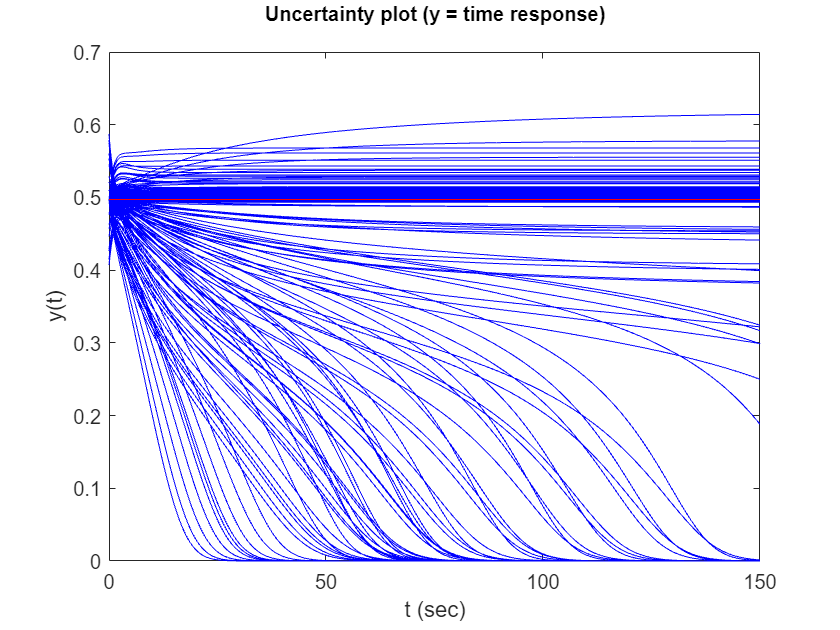

 

graphfontsize = 10;
titlefontsize = 10;
figure
gsua_plot_uncertainty(S)
set(gca, 'FontSize', graphfontsize);
title(get(gca,'Title').String,'FontSize', titlefontsize);

clear graphfontsize titlefontsize

### 5.2. First-order sensitivity indices plot for output = y (S1)

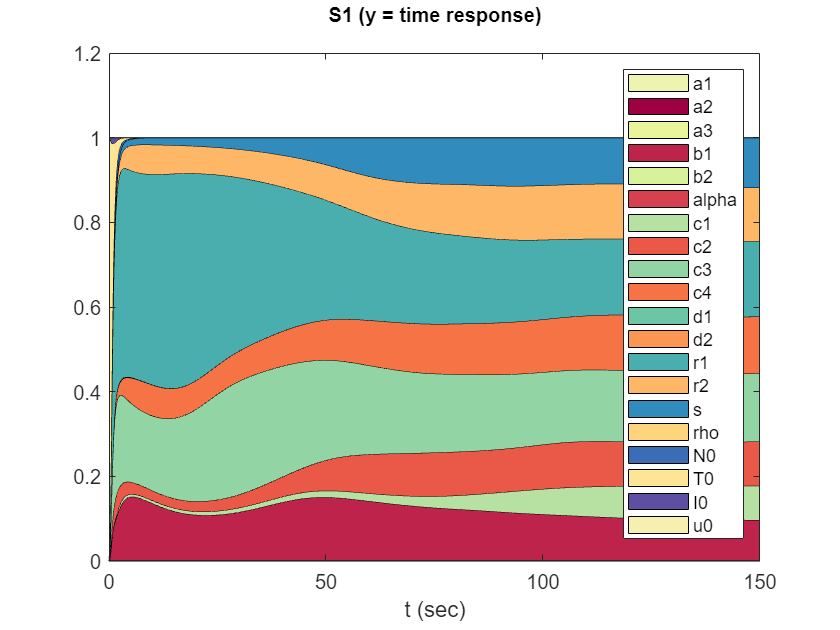

 

plot_type = 'pie'; % If y = scalar
graphfontsize = 10;
titlefontsize = 10;
figure
gsua_plot_sensitivity('S1',S,plot_type)
set(gca,'FontSize', graphfontsize);
title(get(gca,'Title').String,'FontSize', titlefontsize);
h = get(gca, 'Children');
colors=linspecer(length(h));
for i=1:length(h)
    if ~mod(i,2)
        set(h(i), 'FaceColor', colors(i/2,:));
    else
        set(h(i), 'FaceColor', colors(10+(i+1)/2,:));
    end
end

clear titlefontsize graphfontsize plot_type h colors i
if max(sum(S.S1,1))>1 || min(S.S1,[],'all')<0
    disp('Try to use a longer N.')
    disp('The first-order indices must be positive and their sum should be less than 1,')
    disp('so if these conditions are not met, it is necessary to increase N.')
end

Try to use a longer N.


The first-order indices must be positive and their sum should be less than 1,


so if these conditions are not met, it is necessary to increase N.


### 5.3. Total sensitivity indices plot for output = y (ST) 

 

figure
if ~isempty(S.ST)
    plot_type = 'pie'; % If y = scalar
    graphfontsize = 10;
    titlefontsize = 12;
    gsua_plot_sensitivity('ST',S,plot_type)
    set(gca,'FontSize', graphfontsize);
    title(get(gca,'Title').String,'FontSize', titlefontsize);
    h = get(gca, 'Children');
    colors=linspecer(length(h));
    for i=1:length(h)
        if ~mod(i,2)
            set(h(i), 'FaceColor', colors(i/2,:));
        else
            set(h(i), 'FaceColor', colors(10+(i+1)/2,:));
        end
    end
else
    disp('This plot does not apply for this method')
end

This plot does not apply for this method


clear titlefontsize plot_type graphfontsize h colors i

### 5.4. First-order sensitivity indices for output = "scalar characteristic" (S1s)

The first-order indices must be positive and their sum should be less than one, so if these conditions are not met, it is necessary to increase sample size N.

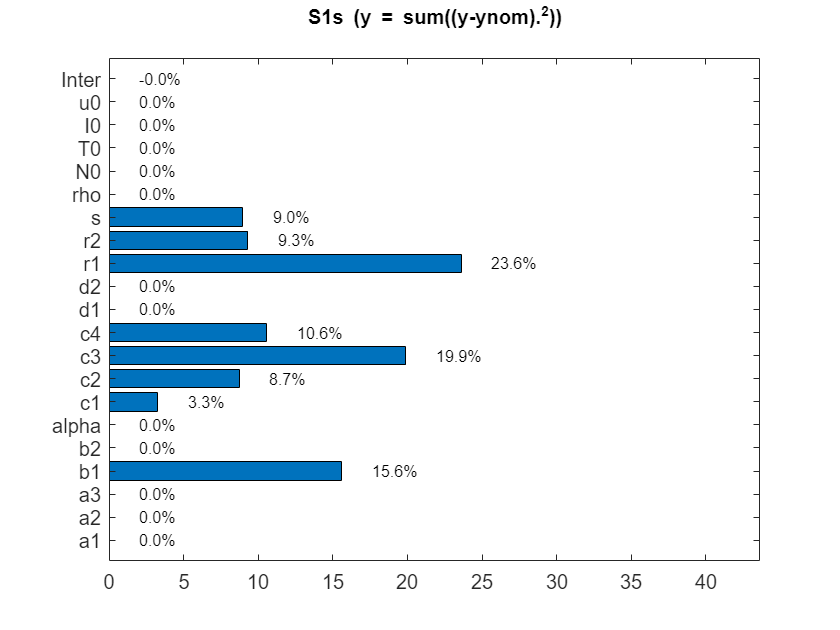

 

plot_type = 'barh';
graphfontsize = 10;
titlefontsize = 10;
figure
gsua_plot_sensitivity('S1s',S,plot_type)
set(gca, 'FontSize', graphfontsize);
title(get(gca,'Title').String,'FontSize', titlefontsize);

clear titlefontsize graphfontsize plot_type
if max(sum(S.S1s))>1 || min(S.S1s)<0
    disp('Try to use a longer N.')
    disp('The first-order indices must be positive and their sum should be less than 1,')
    disp('so if these conditions are not met, it is necessary to increase N.')
end

Try to use a longer N.


The first-order indices must be positive and their sum should be less than 1,


so if these conditions are not met, it is necessary to increase N.


### 5.5. Total sensitivity indices for output = "scalar characteristic" (STs)

 

plot_type = 'barh';
graphfontsize = 10;
titlefontsize = 10;
figure
if ~isempty(S.STs)
    gsua_plot_sensitivity('STs',S,plot_type)
    set(gca, 'FontSize', graphfontsize);
    title(get(gca,'Title').String,'FontSize', titlefontsize);
else
    disp('This plot does not apply for this method')
end

This plot does not apply for this method


clear titlefontsize graphfontsize plot_type

### 5.6. Scatter plots

Scatter plot for scalar output, where Ys is a function of factors. Look for correlations and relative values.

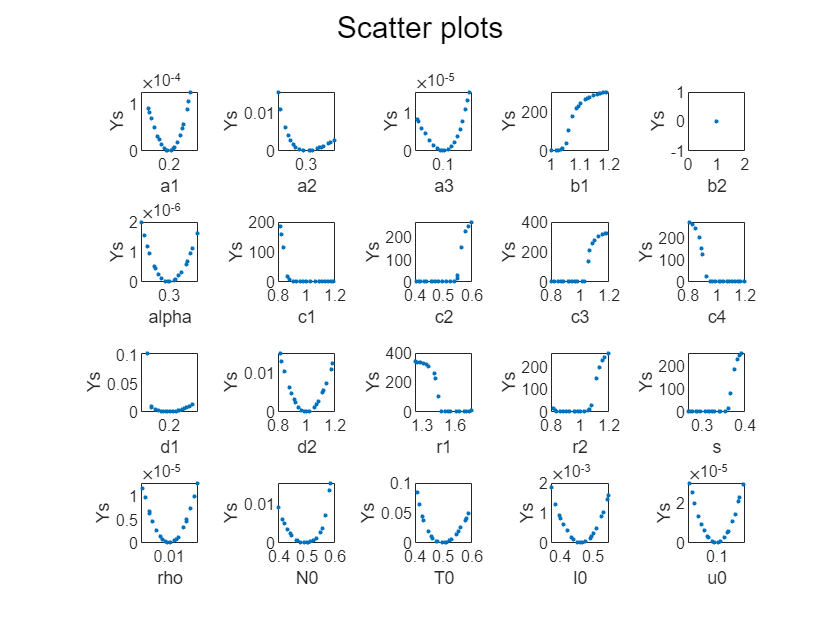

 

figure
gsua_plot_scatter(S)
graphfontsize = 8;
set(findobj(gcf,'type','axes'),'FontSize',graphfontsize);

clear graphfontsize

## 6. References

- Saltelli, A., et al (2010).  Variance based sensitivity analysis of model output. Design and estimator for the total sensitivity index. Computer Physics Communications, 181(2), 259-270.